%此程序用于生成一个考虑了切趾(这里是等距),无分区的大口径光子筛
%clear;
%clc;
%clf;
t1=clock;

f1=2;
D1=0.4;
lamda1=656.45e-9;%Ha线656.45
eta1=1.5;
k=2*pi/lamda1; % 波数

N1=N(D1,lamda1,f1);%算总环数
number=0;   %计数用
%N1=19041;
para=zeros([4,N1]);
%创造每一环的参数
%环半径1
%环宽度2
%每一环的孔径数3
%每一环孔径的直径4
for i=1:N1
    epsilon=0.5;%*win_m(i+N1,2*N1);
    para(1,i)=r_m(i,lamda1,f1);
    para(2,i)=w_m(para(1,i),lamda1,f1);
    para(3,i)=N_m(epsilon,eta1,para(1,i),para(2,i));
    para(4,i)=eta1*para(2,i);
    number=number+para(3,i);
end    

save sample1_para para  N1 number
t2=clock;
etime(t2,t1)

ans = 0.0280

%PMIR=    %用于存放每一个产出的孔径

%用于存储孔径位置
t1=clock;

number0=sum(para(3,1:20));
hole=zeros(3,100);
number1=1;
for i=1:20
    r_m1=para(1,i);
    w_m1=para(2,i);
    N_m1=para(3,i);
    d=para(4,i);
    for j=1:N_m1
        x=r_m1*cos(j);
        y=r_m1*sin(j);
        hole(:,number1)=[x y d/2];
        number1=number1+1;
    end
end
%hole1=hole(:,1:number1-1);  %测试用
save sample1_hole.mat hole
t2=clock;
etime(t2,t1)

ans = 0.0120

%计算大口径光子筛的衍射图样.读取

%load sample1_hole.mat
%load sample1_para.mat

%用于处理内环
t1=clock;
X=meshgrid(-2e-5:1e-7:2e-5);
Y=meshgrid(-2e-5:1e-7:2e-5).';
size1=size(X,1);
U1=zeros(size1,size1);
for i=1:number1-1 %由前二十环记点得
    an=double(hole(3,i));
    xn=double(hole(1,i));
    yn=double(hole(2,i));
    U1=U1+U_n(X,Y,k,1,f1,0,an,xn,yn,0,0);
end
t2=clock;
etime(t2,t1)

ans = 15.7800

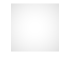

U1=abs(U1);
U1_max=max(max(U1));
imshow(U1/U1_max)


RI = imref2d(size(U1));
RI.XWorldLimits = [-2e-5 2e-5];
RI.YWorldLimits = [-2e-5 2e-5];
figure
%plot(0:1e-7:2e-5,U3R/max(U3R))
%U2=zeros(size1,size1);

%用于处理外环
t1=clock;
U2R=zeros(1,201);%取样间隔1e-6
%这用于获得一个径向的分布
for m=21:N1
    U2R=U2R+U_m(para(3,m),k,1,f1,para(4,m)/2,para(1,m),0:1e-7:2e-5);
end

U1R=U1(201,201:end);
U3R=U1R+U2R;
U3R=abs(U3R);
t2=clock;
etime(t2,t1)

ans = 1.1420


U3R3=U3R;   %懒,这是一个用来验证切趾影响的操作

clf
plot(0:1e-7:2e-5,U3R1);

函数或变量 'U3R1' 无法识别。

hold on
plot(0:1e-7:2e-5,U3R2);
hold on
plot(0:1e-7:2e-5,U3R3)
hold off
legend('unmodulated','Gauss0.4','Gauss0.5')

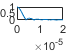

%画图(这个心的结构是精度的问题)
plot(0:1e-7:2e-5,U3R/max(U3R))

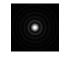

U2=zeros(size1,size1);
%反正这个计算需要的资源不多,再跑一遍吧,来获得一个稍大点的圆覆盖我的范围
U2R=zeros(1,301);
for m=21:N1
    U2R=U2R+U_m(para(3,m),k,1,f1,para(4,m)/2,para(1,m),0:1e-7:3e-5);
end

for i=1:size1
    for j=1:size1
        r=((i-201)^2+(j-201)^2)^0.5*1e-7;
        U2(i,j)=U2R(1,fix(r/1e-7)+1);
    end
end

U3=abs(U1+U2);
%U3=log10(U3);
U3_max=max(max(U3));
U3=U3./U3_max;
save sample1_end U3
imshow(U3)

RI = imref2d(size(U3));
RI.XWorldLimits = [-2e-5 2e-5];
RI.YWorldLimits = [-2e-5 2e-5];
figure
%imshow(U3,RI)

function r=r_m(m,lamda,f)   %算环带半径
    r=(m^2*lamda^2+2*m*lamda*f)^0.5;
end

%算环带间隔,明带,自变量明带半径
function w=w_m(R,lamda,f)
    w=lamda*f/(2*R);
end

%算环带数
function n=N(D,lamda,f)
    n=fix(D*D/(8*f*lamda));
end

%按照指定填充因子计算m环孔径数
function N=N_m(epsilon,eta,r_m0,w_m0)
    N=fix(epsilon*2*pi*r_m0/(eta*w_m0));
end

%"大口径光子筛小孔环带设计方法研究_周润"高斯窗等距切趾,0.4是高斯参数
function win1=win_m(n,N)
    win1=exp(-0.5*((n-0.5*(N-1))/(0.5*0.5*(N-1)))^2);
end

%以下用来算相位面
function U1=U_n(X,Y,k,An,q,Ln,an,xn,yn,gn,hn)
%我希望X,Y是矩阵
%An孔径中心的振幅,近似代表整个,L_n,孔径中心的相位等效光程,(2.24)
    H=(q^2+(X-xn).^2+(Y-yn).^2).^0.5;
    rou=((X-xn-gn.*H).^2+(Y-yn-hn.*H).^2).^0.5;
    U1=(k*An*q*an^2./(H.^2)).*exp(1j*k*(H+Ln)).*besselj(1,k*an*rou./H)./(k*an*rou./H);
end

function U2=U_m(Nm,k,Am,q,am,rm,R)
%以环带模型计算每环带的谱,记得考略环带模型的限制条件,以及后续可能需要评估一下精度误差
H0=(q^2+R.^2+rm^2).^0.5;
U2=Nm*k*Am*q*am^2./H0.^2.*besselj(1,k*am*rm./H0)./(k*am*rm./H0).*exp(1j*k*H0).*besselj(0,k*R*rm./H0);
end